# ***LCS hw5 Software assignment***

## ***Dr.Behzad Ahi***

## ***MohammadParsa Dini - 400101204***

***Problem 6:***

***part 1: ***Input noise:

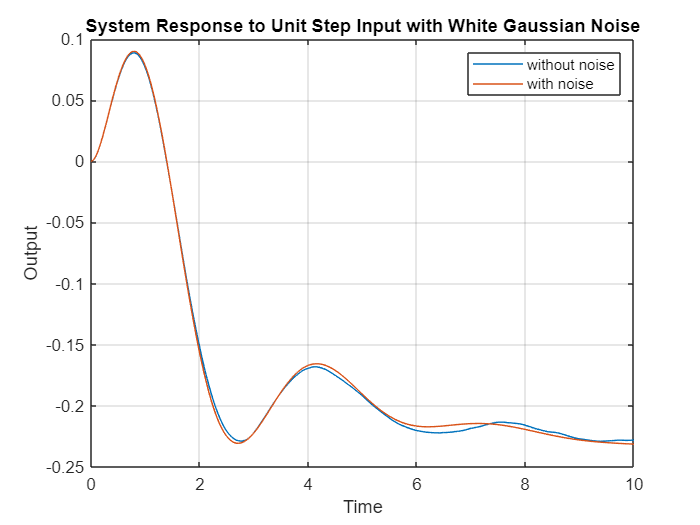

clc; clear; close all;
% Define the parameters
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3;  

num = k * conv([b1, 1], [1, -b2]);
den = conv([tau1, 1], [tau2, 1]);   
den = conv(den, [1, 2*zeta*wn, wn^2]);

% Create transfer function G(s)
G = tf(num, den);

% Define the time vector
t = linspace(0, 10, 1000); % Change the time range and number of points as needed

% Generate a unit step input
u = ones(size(t));

% Generate white Gaussian noise with mean 0 and standard deviation 0.1
noise = 0.1 * randn(size(t));

% Add noise to the input
u_with_noise = u + noise;

% Simulate the system's response to the input with noise
[y, ~, ~] = lsim(G, u_with_noise, t);
[yy,v,vv] = lsim(G, u, t);

% Plot the output response
figure;
plot(t, y);
hold on
plot(t, yy);
xlabel('Time');
ylabel('Output');
title('System Response to Unit Step Input with White Gaussian Noise');
legend('without noise','with noise')
grid on;

As you can see, there is not much difference, since the SNR of input was hogh, if we add a WGN with more energy we might see

much more deviations in that case:

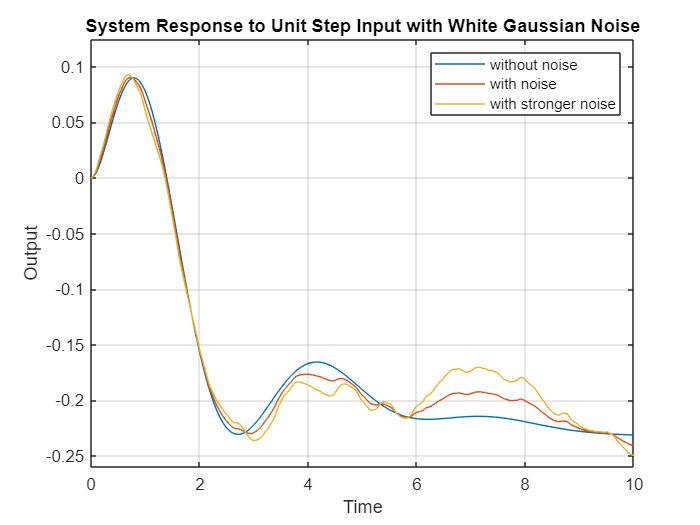

clc; clear; close all;
% Define the parameters
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3;  

num = k * conv([b1, 1], [1, -b2]);
den = conv([tau1, 1], [tau2, 1]);   
den = conv(den, [1, 2*zeta*wn, wn^2]);

% Create transfer function G(s)
G = tf(num, den);

% Define the time vector
t = linspace(0, 10, 1000); % Change the time range and number of points as needed

% Generate a unit step input
u = ones(size(t));

% Generate white Gaussian noise with mean 0 and standard deviation 0.1
noise = 0.5 * randn(size(t));

% Add noise to the input
u_with_noise = u + noise;
u_with_noise_ = u + 2*noise;

% Simulate the system's response to the input with noise
[y, ~, ~] = lsim(G, u_with_noise, t);
[yy,v,vv] = lsim(G, u, t);
[yyy, vvv, gg] = lsim(G, u_with_noise_, t);

% Plot the output response
figure;
plot(t, yy);
hold on
plot(t, y);
hold on;
plot(t, yyy);
xlabel('Time');
ylabel('Output');
title('System Response to Unit Step Input with White Gaussian Noise');
legend('without noise','with noise','with stronger noise');
ylim([-.26 0.125]);
grid on;

As we can see, the difference between the ideal output and noisy output will rise as time passes. Furthermore, in contrast to the ideal case, the noisy output is not smoothely changing and it has much more high frequency.

***Problem 6:***

***part 2: ***Output noise

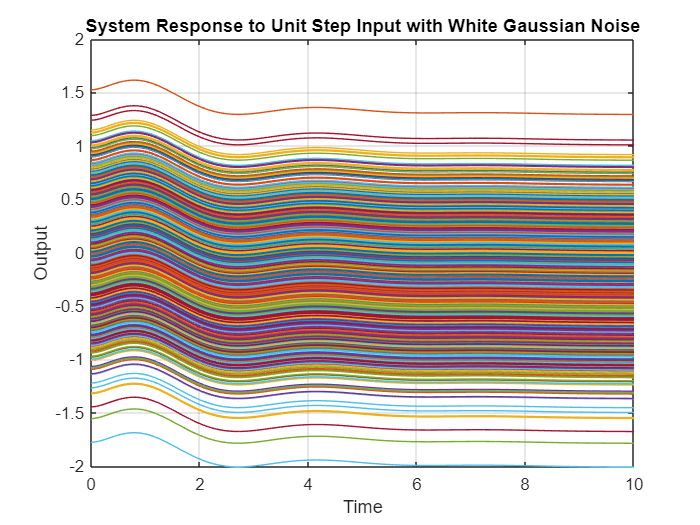

clc; clear; close all;
% Define the parameters
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3;  

num = k * conv([b1, 1], [1, -b2]);
den = conv([tau1, 1], [tau2, 1]);   
den = conv(den, [1, 2*zeta*wn, wn^2]);

% Create transfer function G(s)
G = tf(num, den);

% Define the time vector
t = linspace(0, 10, 1000); % Change the time range and number of points as needed

% Generate a unit step input
u = ones(size(t));

% Generate white Gaussian noise with mean 0 and standard deviation 0.1
noise = 0.1 * randn(size(t));

% Simulate the system's response to the input with noise
[y, ~, ~] = lsim(G, u, t);
 
y1 = y + noise;
y2 = y + 5*noise;
% Plot the output response
figure;
plot(t, y);
hold on
plot(t, y1 - y);
hold on;
plot(t, y2);
xlabel('Time');
ylabel('Output');
title('System Response to Unit Step Input with White Gaussian Noise');
%legend('without noise','with noise','with stronger noise');
grid on;

***Problem 6:***

***part C:***

Here we tuned $k$ from .5 to 1.5 or equivalently with 50 percent deviation in its ideal case:

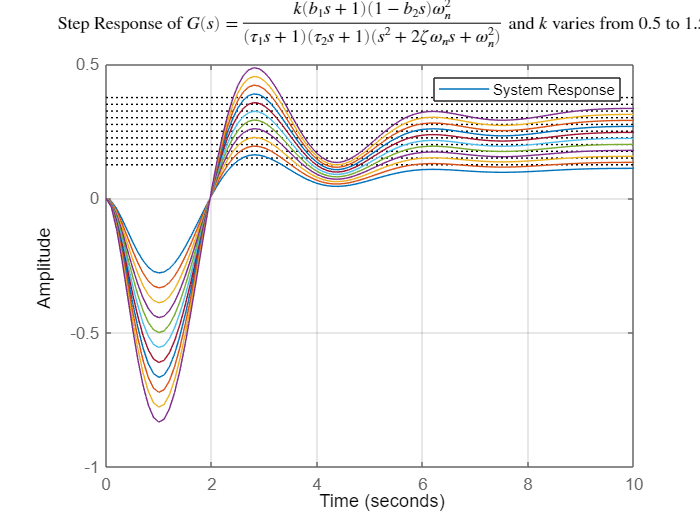

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 0.5:0.1:1.5;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating k
for i = 1:length(param)
    hold on
    num = param(i)*(b1*s + 1)*(1 - b2 *s*wn^2);    
    den = (tau2*s+1)*(tau1*s+1)*(s^2 + 2*zeta*wn*s + wn^2);  
    H_sys = tf(sym2poly(num), sym2poly(den));  
    t = 0:0.1:10;  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $k$ ' ...
        'varies from 0.5 to 1.5'], ...
        'interpreter', 'latex');

    grid on;
    legend('System Response');
end

As we can see, as $k$ rises, the amplitude of the output will rise as well.

***Problem 6:***

***part D:***

Here we tuned $\tau_1$ from 0.25 to 0.75 or equivalently with 50 percent deviation in its ideal case:

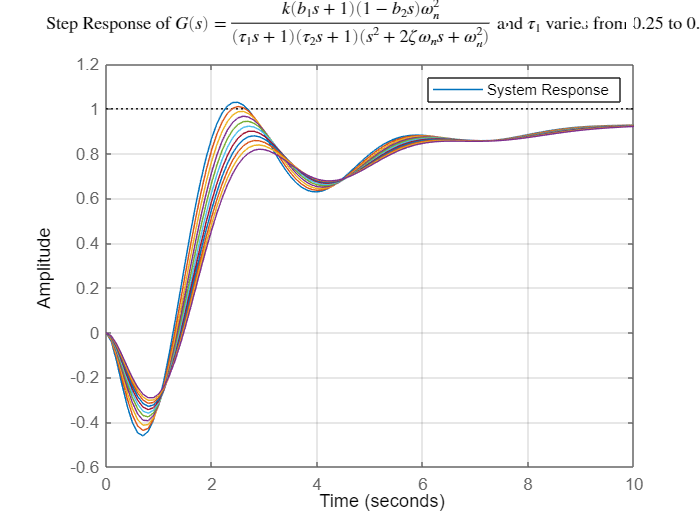

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 0.25:0.05:0.75;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating tau1
for i = 1:length(param)
    t = 0:0.1:10;
    hold on
    num = k*(b1*s + 1)*(1 -b2 *s)*wn^2;    
    den = (tau2*s+1)*(param(i)*s+1)*(s^2 + 2*zeta*wn*s + wn^2);  
    H_sys = tf(sym2poly(num), sym2poly(den));    
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $\tau_1$ ' ...
        'varies from 0.25 to 0.75'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

As $\tau
_1$ increases, the pole $\frac{1}{\tau_1}$ will be closer to $j\omega$ axis and hence, the amplitude will be lower. Furthermore, the setting time will increase. 

***Problem 6:***

***part E:***

Here we tuned $\tau_2$ from 2.5 to 7.5 or equivalently with 50 percent deviation in its ideal case:

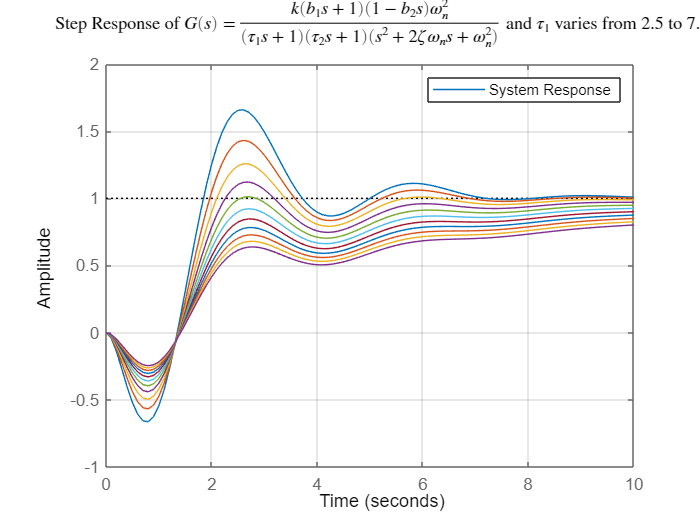

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 2.5:0.5:7.5;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating tau2
for i = 1:length(param)
    t = 0:0.1:10;  
    hold on
    num = k*(b1*s + 1)*(1 - b2 *s)*wn^2;    
    den = (param(i)*s+1)*(tau1*s+1)*(s^2 + 2*zeta*wn*s + wn^2);  
    H_sys = tf(sym2poly(num), sym2poly(den));  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $\tau_1$ ' ...
        'varies from 2.5 to 7.5'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

The same argument will be applied to this part. The amplitude will have less overshoot and the setting time will rise drastically.

***Problem 6:***

***part F:***

Here we tuned $\zeta$ from 0.1 to 0.3 or equivalently with 50 percent deviation in its ideal case:

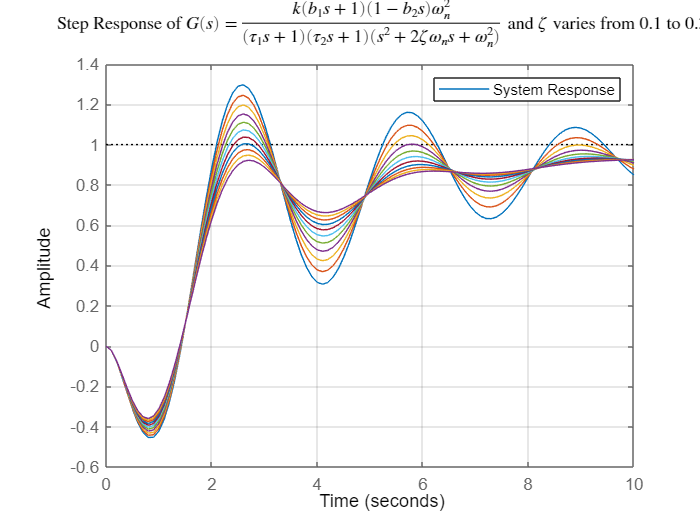

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 0.1:0.02:0.3;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating zeta
for i = 1:length(param)
    t = 0:0.1:10;  
    hold on
    num = k*(b1*s + 1)*(1 - b2 *s)*wn^2;    
    den = (tau2*s+1)*(tau1*s+1)*(s^2 + 2*param(i)*wn*s + wn^2);  
    H_sys = tf(sym2poly(num), sym2poly(den));  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $\zeta$ ' ...
        'varies from 0.1 to 0.3'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

By increasing $\zeta$, the overshoot will shrink since $overshoot = f_v \times e^{- \frac{\pi \zeta}{\sqrt{1 - \zeta^2}}}$( we assumed this function will behave as a 2nd order function). and furthermore, the setting time will be lowered.

***Problem 6:***

***part G:***

Here we tuned $\omega_n$ from 1 to 3 or equivalently with 50 percent deviation in its ideal case:

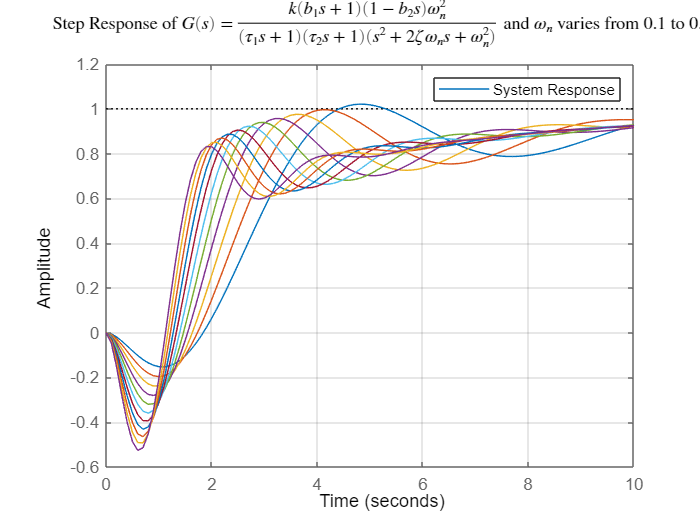

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 1:0.2:3;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating wn
for i = 1:length(param)
    hold on
    num = k*(b1*s + 1)*(1 - b2 *s)*param(i)^2;    
    den = (tau2*s+1)*(tau1*s+1)*(s^2 + 2*zeta*param(i)*s + param(i)^2);
    H_sys = tf(sym2poly(num), sym2poly(den));  
    t = 0:0.1:10;  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $\omega_n$ ' ...
        'varies from 0.1 to 0.3'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

***Problem 6:***

***part G:***

Here we tuned $b_1
$ from 1 to 3 or equivalently with 50 percent deviation in its ideal case:

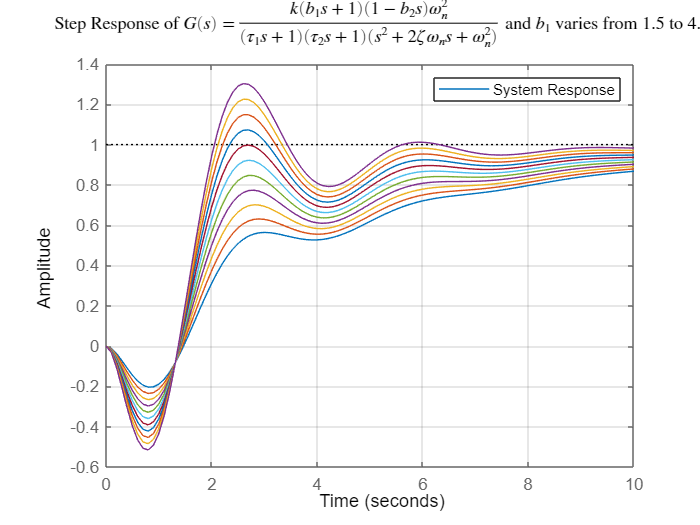

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 1.5:0.3:4.5;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating b1
for i = 1:length(param)
    hold on
    num = k*(param(i)*s + 1)*(1 - b2 *s)*wn^2;    
    den = (tau2*s+1)*(tau1*s+1)*(s^2 + 2*zeta*wn*s + wn^2);
    H_sys = tf(sym2poly(num), sym2poly(den));  
    t = 0:0.1:10;  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $b_1$ ' ...
        'varies from 1.5 to 4.5'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

***Problem 6:***

***part H:***

Here we tuned $b_2
$ from 1 to 3 or equivalently with 50 percent deviation in its ideal case:

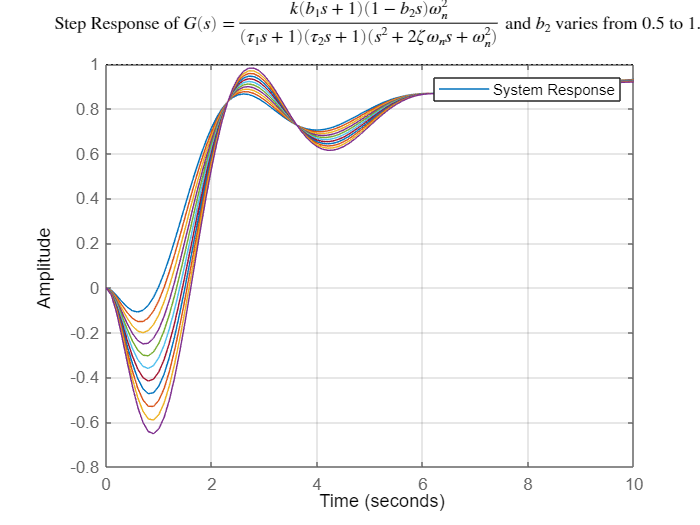

clc; clear; close all;
syms s
% Defining the parameters of the transfer function
param = 0.5:0.1:1.5;
k = 1;       
b1 = 3;   
b2 = 1;     
wn = 2;       
tau1 = 0.5;  
tau2 = 5;   
zeta = 0.3; 
% loop for deviating b2
for i = 1:length(param)
    hold on
    num = k*(b1*s + 1)*(1 - param(i) *s)*wn^2;    
    den = (tau2*s+1)*(tau1*s+1)*(s^2 + 2*zeta*wn*s + wn^2);
    H_sys = tf(sym2poly(num), sym2poly(den));  
    t = 0:0.1:10;  
    step(H_sys, t);
    xlabel('Time');
    ylabel('Amplitude');
    title(['Step Response of $G(s) = \frac{k(b_1 s + 1)(1 - b_2 s)\omega_n^2}' ...
        '{( \tau_1 s + 1)(\tau_2 s + 1)(s^2 + 2\zeta\omega_n s + \omega_n^2)}$ and $b_2$ ' ...
        'varies from 0.5 to 1.5'], ...
        'interpreter', 'latex');
    grid on;
    legend('System Response');
end

***Problem 7:***

***System 1:***

***Part A,B:***

clc; clear; close all;

s = tf('s');
numer1 = s^2 + 2*s + 2;
denominat1 =  s^3 + 0.25*s;
sys1 = numer1/denominat1

sys1 =
 
  s^2 + 2 s + 2
  -------------
  s^3 + 0.25 s
 
Continuous-time transfer function.



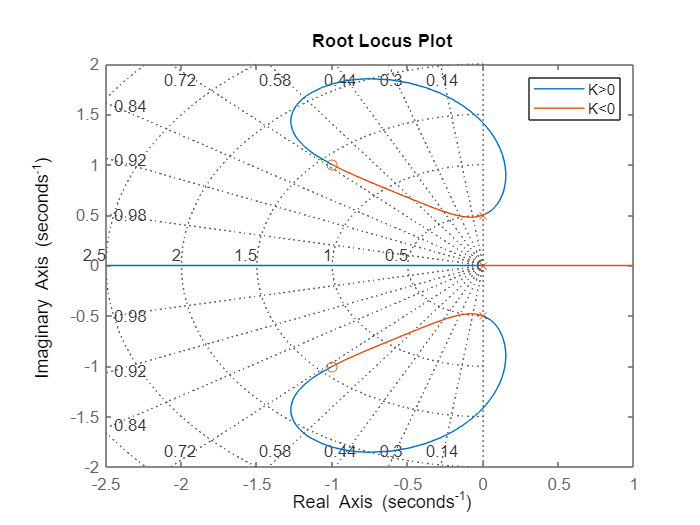

figure;
rlocus(sys1,-sys1);
legend('K>0','K<0');
title('Root Locus Plot');
grid on

And here using the `find_breakaway_points(sys) function we took system's trtransferr function as an input and `

 we found the breakaway points by finding the roots of $\frac{d}{ds} G(s) = 0$: 

Here is implementation of the desired function and also its output:

We also know that for finding the complementary rooy locus it suffices to take -G(s) as input:

% function [breakaway_points] = find_breakaway_points(sys)
%     syms s;
%     num = sys.Numerator;
%     den = sys.Denominator;
%     % Create symbolic expressions for the transfer function and its derivative
%     G = poly2sym(num, s) / poly2sym(den, s);
%     G_prime = diff(abs(G), s);
%     
%     % Find the critical points where the derivative is zero
%     critical_points = vpasolve(G_prime == 0, s);
%     
%     % Evaluate the critical points to determine breakaway points
%     breakaway_points = [];
%     for i = 1:length(critical_points)
%         if isreal(critical_points(i)) && abs(critical_points(i)) ~= Inf
%             breakaway_points = [breakaway_points; double(critical_points(i))];
%         end
%     end
% end
break_aways =  find_breakaway_points(sys1)


break_aways =

     []



Thus, there are no braking points in this system, since the list of` break_aways` is null.

***System 2:***

***Part A,B:***

clc; clear; close all;

s = tf('s');
numer2 = s^2;
denominat2 =  (s^2 - 1)^2;
sys2 = numer2/denominat2

sys2 =
 
        s^2
  ---------------
  s^4 - 2 s^2 + 1
 
Continuous-time transfer function.



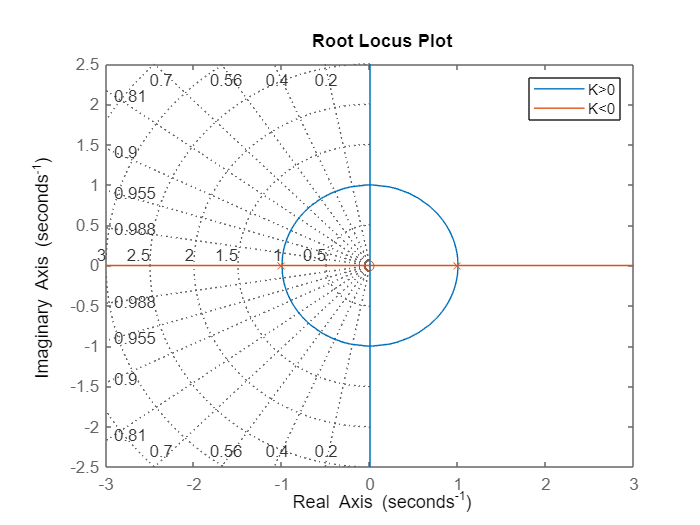

figure;
rlocus(sys2,-sys2);
legend('K>0','K<0');
title('Root Locus Plot');
grid on

***Part C:***

***System 1:***

Here using the manipulator function we will output:

1)the points which belong to root-locus 

2) The points which belong to complementary root-locus 

3) The candidate points which neither belong to root-locus, nor to its complementary plot 

clc; clear; close all;
syms s
G(s) = (s^2 + 2*s + 2)/(s *(s^2 + 0.25));
[k_pos ,k_neg, others] = Manipulator(G,s)

 
k_pos =
 
Empty sym: 0-by-1
 
 
k_neg =
 
Empty sym: 0-by-1
 


$$others = \left(\begin{array}{c} -2.0291289456597803634180201034811-1.3357918919869738626969712269717\,\mathrm{i}\\ -2.0291289456597803634180201034811+1.3357918919869738626969712269717\,\mathrm{i}\\ 0.029128945659780363418020103481059-0.28960800211921472630369875126637\,\mathrm{i}\\ 0.029128945659780363418020103481059+0.28960800211921472630369875126637\,\mathrm{i} \end{array}\right)$$

***System 2:***

clc; clear; close all;
syms s
G(s) = (s^2 / ((s^2-1)^2));
[k_pos ,k_neg, others] = Manipulator(G,s)

 
k_pos =
 
Empty sym: 0-by-1
 


$$k\_neg = \left(\begin{array}{c} -1.0\,\mathrm{i}\\ 1.0\,\mathrm{i} \end{array}\right)$$

 
others =
 
Empty sym: 0-by-1
 


which in both cases alligns with what we have got in the first place.

function [breakaway_points] = find_breakaway_points(sys)
    syms s;
    num = sys.Numerator;
    den = sys.Denominator;
    % Create symbolic expressions for the transfer function and its derivative
    G = poly2sym(num, s) / poly2sym(den, s);
    G_prime = diff(abs(G), s);
    
    % Find the critical points where the derivative is zero
    critical_points = vpasolve(G_prime == 0, s);
    
    % Evaluate the critical points to determine breakaway points
    breakaway_points = [];
    for i = 1:length(critical_points)
        if isreal(critical_points(i)) && abs(critical_points(i)) ~= Inf
            breakaway_points = [breakaway_points; double(critical_points(i))];
        end
    end
end


function [k_pos,k_neg,others] = Manipulator(H_sys , s) 
% we know that the breakaway points can be found 
% using solving d/ds G(s) =0
sol = vpasolve(diff(H_sys , s) == 0,s);    
point = H_sys(sol);                    
reals = (imag(point) == 0);
% first we will separate the complex roots 
% since they must belong to the reral axis 
others = sol(~reals);
idga = imag(point) == 0 & real(point) > 0; 
idgc = imag(point) == 0 & real(point) < 0;     
k_pos = sol(idga);                   
k_neg = sol(idgc);                  
end